clear all; clc

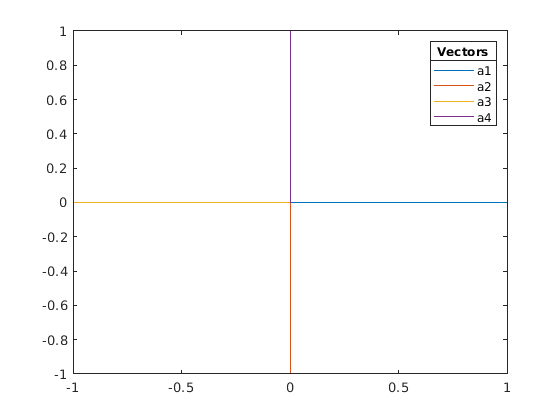

origin = [0,0];
a = 1; % separation between points (lattice separation)
a1 = [a, 0];
a2 = [0, -a];
a3 = [-a, 0];
a4 = [0, a];

vectors =[a1;a2;a3;a4];
plot_vectors(vectors') % uncomment this code to see the lattice vectors

%{                 
                     N
                     |
Some more info   W-------E
                     |
                     S
First NN : E
Second NN : S
Third NN : W
Fourth NN : N

%}

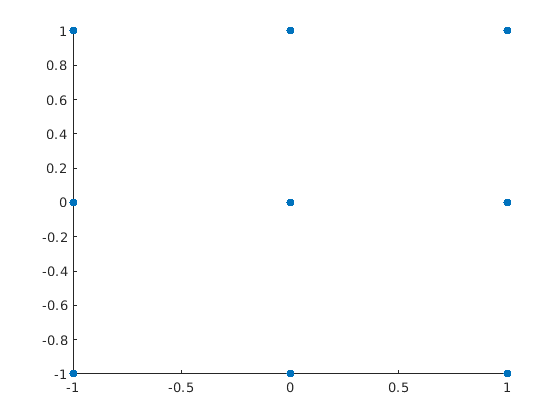

str = 'PBC'; % You can choose periodic BC or Closed BC ( PBC or CB)
lmax = 1; % final coordinate along x and y direction
lmin = -1; % inital along x and y direction. square lattice runs from lmin to lmax.
nsite = ((lmax - lmin)/a + 1) ^ 2; % Number of lattice points.
nnb = 4;
site_index = 2;
nn_mat = zeros(nsite,nnb);
site_pos = zeros(1,2);
temp_site_pos = zeros(nnb,2);

for site = 1 : nsite
    for nbd = 1 : nnb
        origin = site_pos(site,:); % Setting site position as origin
        pos = origin + vectors(nbd,:); % Finding site position along the vectors
        val = ismember(pos,site_pos); % checking if the site position coincide with previous site positions 
        index = find_index(site_pos,pos);
        if pos(1,1) > lmax || pos(1,2) >lmax || pos(1,1) < lmin || pos(1,2) < lmin %checking the bounds
            switch str
                case 'PBC'
                    x = origin(1,1); 
                    y = origin(1,2);
                    if vectors(nbd,:) == a1
                        new_pos = [-x,y]; % we need to flip x-axis here to get the PBC(at the bounds)
                    elseif vectors(nbd,:) == a3
                        new_pos = [-x,y];
                    elseif vectors(nbd,:) == a2
                        new_pos = [x,-y]; % we need to flip y-axis here to get the PBC(at the bounds)
                    elseif vectors(nbd,:) == a4
                        new_pos = [x,-y];
                    
                    end
                    index = find_index(site_pos,new_pos);
                    nn_mat(site,nbd) = index;
                    
                case 'CB'
                     nn_mat(site,nbd) = 0; %if out of bounds site is denoted zero(closed BC) 
                    
            end
            
            
        elseif (all(val) ~= 1 || index == 0) 
            temp_site_pos(nbd , :) = pos;  % save the current pos in site_pos database
            nn_mat(site,nbd) = site_index; % Save the index of the site in matrix nn_mat
            site_index = site_index + 1;
        else % current pos matches with previous 
        nn_mat(site,nbd) = index; % instead of placing new value it uses the correct site position
            
        end
      
    end
    temp_site_pos( all(~temp_site_pos,2), : ) = []; % Remove the rows which are zeros from temp_site_pos
    site_pos = vertcat(site_pos,temp_site_pos); % append the temp_site_pos to site_pos
    temp_site_pos = [];
end

visualize(site_pos)

N = nsite; % Total number of sites 
S=4*N;       % Size of BdG Hamiltonian matrix
t=1;         % Electron hopping energy
mu=0;        % Chemical potential
delta0=2;  % Pairing gap
DELS=zeros(N,1);  % Array containg pairing gap (delta_i) at all sites
DELS(:,1)=delta0; % Assigning delta_i at each site to be delta0
NN = nn_mat;

for i=1:N
    H(i,i)=-mu;
    H(i+N,i+N)=-mu;
    H(i+2*N,i+2*N)=mu;
    H(i+3*N,i+3*N)=mu;
    for j=1:4
        k=NN(i,j);
        H(i,k)=-t;
        H(k,i)=conj(H(i,k));
        H(i+N,k+N)=-t;
        H(k+N,i+N)=conj(H(i+N,k+N));
        H(i+2*N,k+2*N)=t;
        H(k+2*N,i+2*N)=conj(H(i+2*N,k+2*N));
        H(i+3*N,k+3*N)=t;
        H(k+3*N,i+3*N)=conj(H(i+3*N,k+3*N));
    end
end

for i=1:N
    H(i,i+3*N)=DELS(i,1);
    H(i+3*N,i)=conj(H(i,i+3*N));
    H(i+N,i+2*N)=-DELS(i,1);
    H(i+2*N,i+N)=conj(H(i+N,i+2*N));
end

[V,E]=eig(H);
E=diag(E);

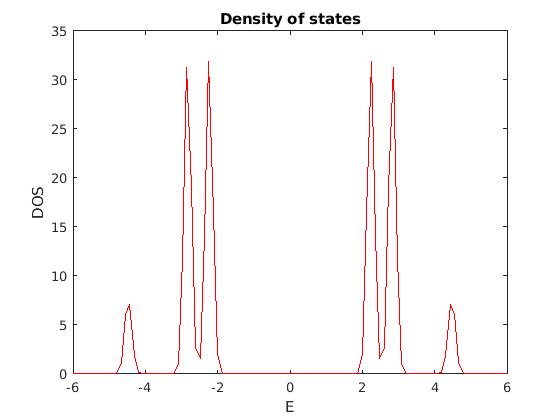

sigma=0.1; % Parameter to compute DOS (variance of the Gaussian)

Num_E=100;
E_min=-6;
E_max=6;
dE=(E_max-E_min)/(Num_E-1);

DOS=zeros(Num_E,2);

a=1;
for e=E_min:dE:E_max
    d=0;
    for l=1:length(E)
        x=e-E(l);
        d=d+1/(sqrt(2*pi*sigma^2))*exp(-(x^2)/(2*sigma^2));
    end
    DOS(a,1)=e;
    DOS(a,2)=d;
    a=a+1;
end



figure,
plot(DOS(:,1),DOS(:,2),'r-')
xlabel 'E'
ylabel 'DOS'
title 'Density of states'

function plot_vectors(vectors)
plotv(vectors,'-')
lgd = legend("a1","a2","a3","a4");
title(lgd,'Vectors')
end

function index = find_index(site_pos, pos)
index1 = find(site_pos == pos(1,1)); % Looks for index of first entry in site_pos
index2 = find(site_pos == pos(1,2)) - length(site_pos); % Looks for index of  second entry in site_pos
index = intersect(index1,index2); % returns index only if two indexes match.
% Sometimes it returns [] because while items exist indices don't match and hence we set index = 0. 
if isempty(index) 
    index = 0;
end

end
